# Charakterystyki czasowe podstawowych obiektów dynamicznych

Mateusz Wójcik, 21.10.2024

clear, clc

## Wstęp - charakterystyki podstawowych obiektów

Celem laboratorium jest zapoznanie się z charakterystykami czasowymi i częstotliwościowymi podstawowych obiektów dynamicznych. W trakcie zajęć zajmowano się obiektami o transmitancjach przedstawionych w poniższej tabeli:

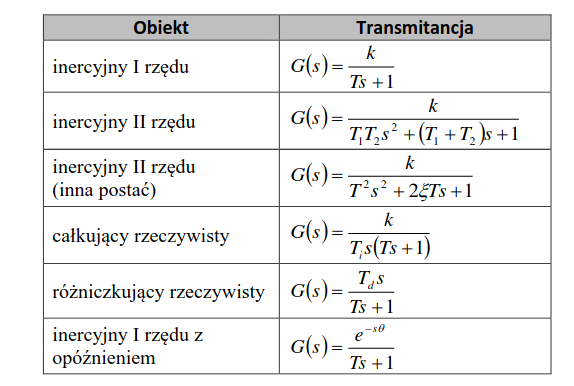

Rozważane obiekty można przedstawić w postaci schematu jako układ blokowy:

W przeprowadzanych rozważaniach skorzystano z dwóch postaci sygnału wejściowego **u(t):**

- **delta Diraca **- dla chartakterystyk impulsowych,

- **skok jednostkowy **- dla charakterystyk skokowych,

Rezultaty w postaci wykresów dla różnych parametrów przedstawiono na poniższych rysunkach.

Definiowanie stałych dla dwóch wersji charakterystyk, aby zapewnić różne kształty wykresów:

% parametry wersja 1
k_v1 = 2;
T_v1 = 1;
T1_v1 = 0.2;
T2_v1 = 0.5;
Ti_v1 = 3;
Td_v1 = 0.2;
ksi_v1 = 0.2;
theta_v1 = 5;

% parametry wersja 2
k_v2 = 3;
T_v2 = 0.5;
T1_v2 = 1;
T2_v2 = 0.4;
Ti_v2 = 1;
Td_v2 = 2.2;
ksi_v2 = 1.2;
theta_v2 = 3;

n = 75; %rząd aproksymacji

## Funkcja wykreślająca charakterystyki czasowe

W celu optymalizacji czasu i miejsca napisano funkcję pozwalającą na łatwe wyświetlanie charakterystyk wcześniej zdefiniowanych obiektów.

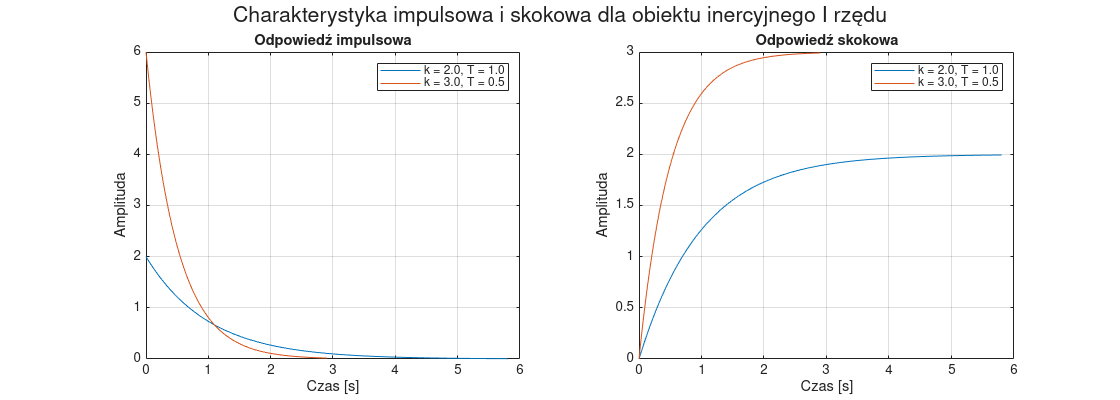

function plot_response(sys1, sys2, plotTitle, leg)
    %PLOT_RESPONSE - ploting impulse and step response of sys1 and sys2
    clf;
    set(gcf, 'Position', [100, 100, 1400, 500]);
    
    sgtitle(plotTitle, 'Fontsize',16);

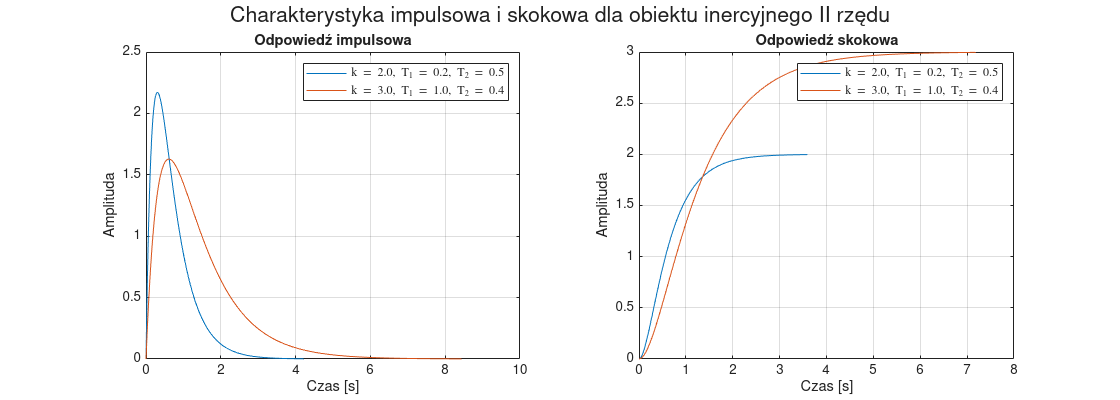

    
    subplot(121)
    [x1, t1] = impulse(sys1);
    [x2, t2] = impulse(sys2);

    plot(t1, x1, t2, x2)
    title('Odpowiedź impulsowa')

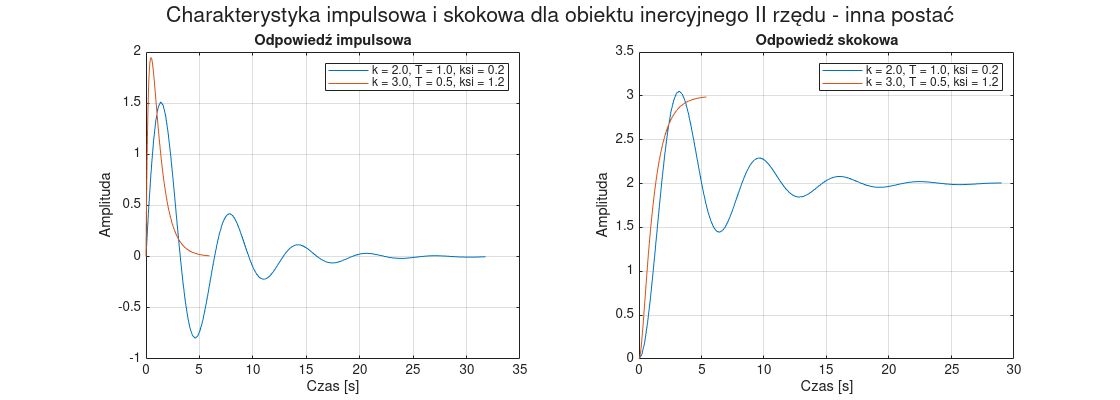

    ylabel("Amplituda")
    xlabel("Czas [s]")
    legend(leg)
    grid on
    
    subplot(122)
    [y1, t1] = step(sys1);
    [y2, t2] = step(sys2);

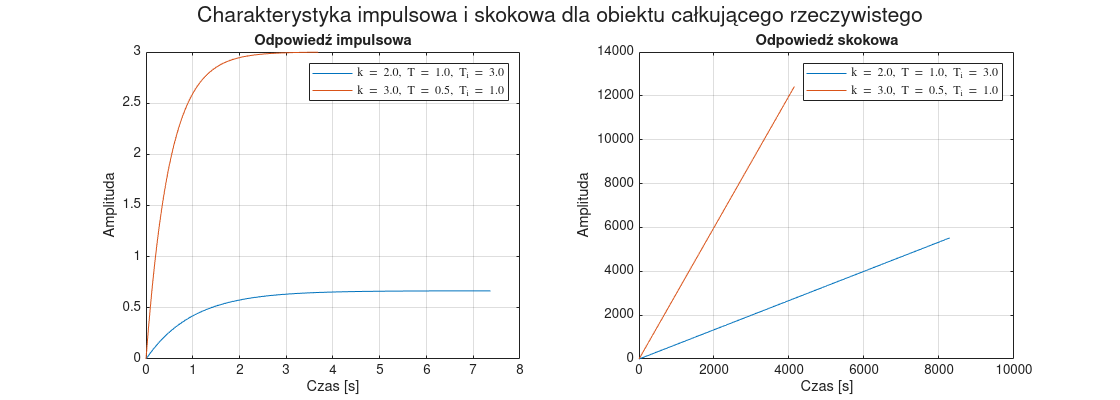

    
    plot(t1, y1, t2, y2)
    title('Odpowiedź skokowa')
    ylabel("Amplituda")
    xlabel("Czas [s]")
    legend(leg)
    grid on


end

## **Charakterystyki czasowe**

Poniżej przedstawiono charakterystyki dla utworzonych obiektów:

**Obiekt inercyjny rzędu I**

obiekt_inercyjny_rzedu_I_v1 = tf([0 k_v1], [T_v1 1]);
obiekt_inercyjny_rzedu_I_v2 = tf([0 k_v2], [T_v2 1]);
title_obiekt ='Charakterystyka impulsowa i skokowa dla obiektu inercyjnego I rzędu';
legend_obiekt = [sprintf("k = %.1f, T = %.1f", k_v1, T_v1), sprintf("k = %.1f, T = %.1f", k_v2, T_v2)];

plot_response(obiekt_inercyjny_rzedu_I_v1, obiekt_inercyjny_rzedu_I_v2, title_obiekt, legend_obiekt);

**Obiekt inercyjny II rzędu**

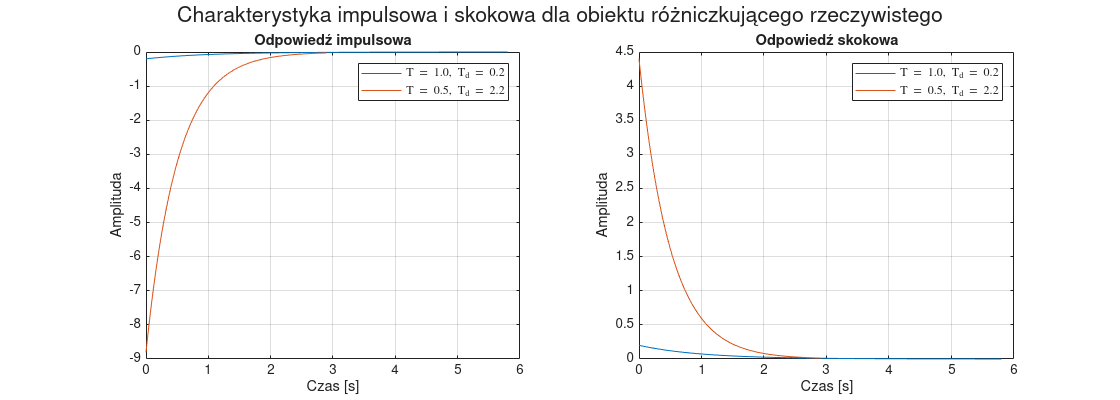

obiekt_inercyjny_rzedu_II_v1 = tf([0 0 k_v1], [T1_v1*T2_v1 T1_v1 + T2_v1 1]);

obiekt_inercyjny_rzedu_II_v2 = tf([0 0 k_v2], [T1_v2*T2_v2 T1_v2 + T2_v2 1]);
title_obiekt ='Charakterystyka impulsowa i skokowa dla obiektu inercyjnego II rzędu';
legend_obiekt = [sprintf("k = %.1f, T_1 = %.1f, T_2 = %.1f", k_v1, T1_v1, T2_v1), sprintf("k = %.1f, T_1 = %.1f, T_2 = %.1f", k_v2, T1_v2, T2_v2)];

plot_response(obiekt_inercyjny_rzedu_II_v1, obiekt_inercyjny_rzedu_II_v2, title_obiekt, legend_obiekt);

**Obiekt inercyjny II rzędu (inna postać)**

obiekt_inercyjny_rzedu_II_ver2_v1 = tf([0 0 k_v1], [T_v1^2 2*T_v1*ksi_v1 1]);
obiekt_inercyjny_rzedu_II_ver2_v2 = tf([0 0 k_v2], [T_v2^2 2*T_v2*ksi_v2 1]);
title_obiekt = 'Charakterystyka impulsowa i skokowa dla obiektu inercyjnego II rzędu - inna postać';
legend_obiekt = [sprintf("k = %.1f, T = %.1f, ksi = %.1f", k_v1, T_v1, ksi_v1), sprintf("k = %.1f, T = %.1f, ksi = %.1f", k_v2, T_v2, ksi_v2)];


plot_response(obiekt_inercyjny_rzedu_II_ver2_v1, obiekt_inercyjny_rzedu_II_ver2_v2, title_obiekt, legend_obiekt);

**Obiekt całkujący rzeczywisty**

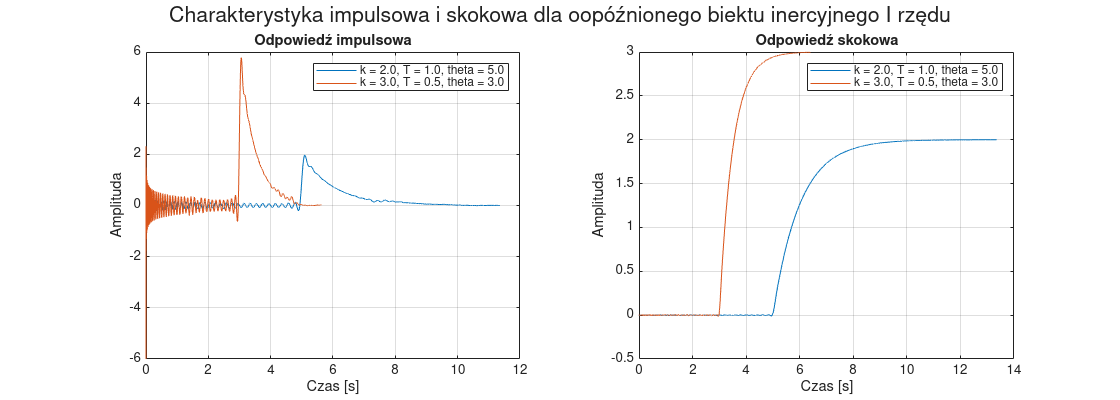

obiekt_calk_recz_v1 = tf([0 0 k_v1], [T_v1*Ti_v1 Ti_v1 0]);
obiekt_calk_recz_v2 = tf([0 0 k_v2], [T_v2*Ti_v2 Ti_v2 0]);
title_obiekt = 'Charakterystyka impulsowa i skokowa dla obiektu całkującego rzeczywistego';
legend_obiekt = [sprintf("k = %.1f, T = %.1f, T_i = %.1f", k_v1, T_v1, Ti_v1), sprintf("k = %.1f, T = %.1f, T_i = %.1f", k_v2, T_v2, Ti_v2)];



plot_response(obiekt_calk_recz_v1, obiekt_calk_recz_v2, title_obiekt, legend_obiekt);

**Obiekt różniczkujący rzeczywisty**

obiekt_rozn_recz_v1 = tf([Td_v1 0], [T_v1 1]);
obiekt_rozn_recz_v2 = tf([Td_v2 0], [T_v2 1]);
title_obiekt = 'Charakterystyka impulsowa i skokowa dla obiektu różniczkującego rzeczywistego';
legend_obiekt = [sprintf("T = %.1f, T_d = %.1f", T_v1, Td_v1), sprintf("T = %.1f, T_d = %.1f", T_v2, Td_v2)];


plot_response(obiekt_rozn_recz_v1, obiekt_rozn_recz_v2, title_obiekt, legend_obiekt);

**Obiekt inercyjny I rzędu z opóźnieniem**

Dla tego obiektu najpierw należało skonstruować obiekt opóźniający, wyznaczając jego transmitancję. Transmitancja szukanego obiektu to połączenie szeregowe transmitancji obiektu opóźniającego i obiektu inercyjnego I rzędu.

**1.Wyznaczamy transmitacje obiektu opóźniającego:**

W celu obliczenia transmitancji obiektu opóźniającego, należy skorzystać z aproksymacji Pade'go, w celu uzyskania wyrazu $e^{-s\theta}$ w postaci wielomianowej o stopniu określonym przez parametr n.

[licz_op1, mian_op1] = pade(theta_v1, n);
op_v1 = tf(licz_op1, mian_op1);
[licz_op2, mian_op2] = pade(theta_v2, n);
op_v2 = tf(licz_op2, mian_op2);

**2. Wykreślamy wykresy **

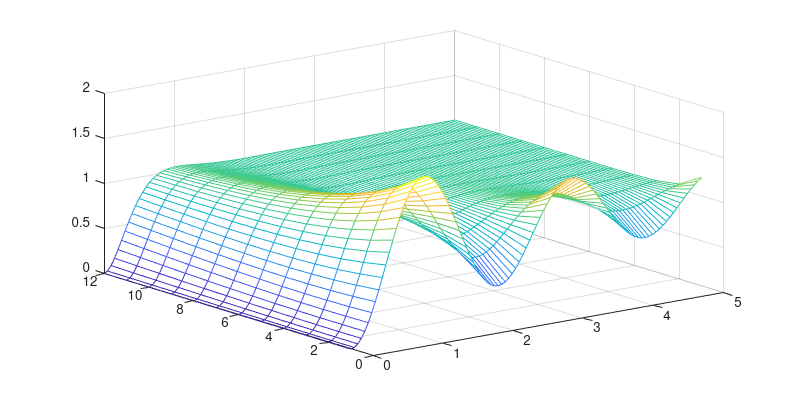

obiekt_op_inercyjny_rzedu_I_v1 = op_v1 *obiekt_inercyjny_rzedu_I_v1;

obiekt_op_inercyjny_rzedu_I_v2 = op_v2 * obiekt_inercyjny_rzedu_I_v2;
title_obiekt = 'Charakterystyka impulsowa i skokowa dla oopóźnionego biektu inercyjnego I rzędu';

legend_obiekt = [sprintf("k = %.1f, T = %.1f, theta = %.1f", k_v1, T_v1, theta_v1), sprintf("k = %.1f, T = %.1f, theta = %.1f", k_v2, T_v2, theta_v2)];


plot_response(obiekt_op_inercyjny_rzedu_I_v1, obiekt_op_inercyjny_rzedu_I_v2, title_obiekt, legend_obiekt);

Łatwo zauważyćm że zastosowanie większej aproksymacji zwiększa wygładzenie początkowej fazy wykresu. Spowodowane jest to przez błedy aproksymacji liczby $e^{-s\theta}$. Ciekawym spostrzeżeniem jest również, fakt, że dla zbyt wysokiej aproksymacji możemy  otrzymać obiekt, którego charakterystyka impulsowa orraz skokowa wskazują na niestabilność.

## Wpływ zer i biegunów na kształt odpowiedzi skokowej

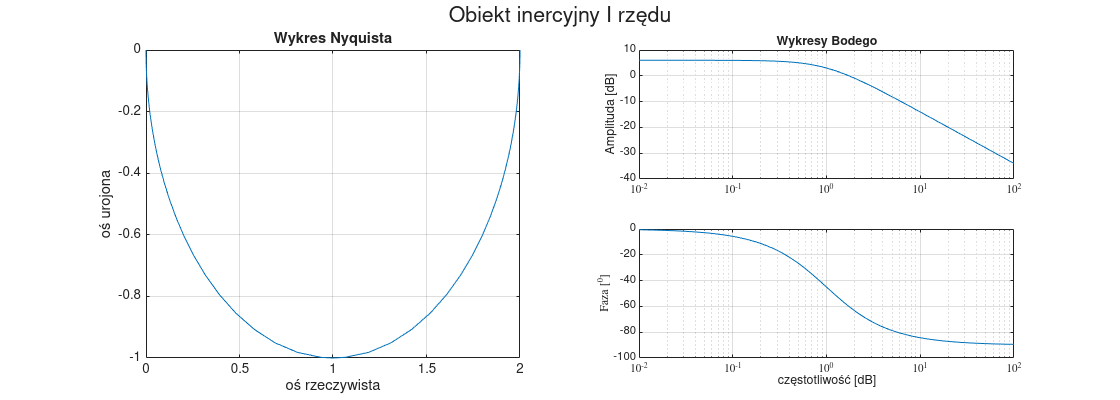

clf
set(gcf, 'Position', [100, 100, 1000, 500]);

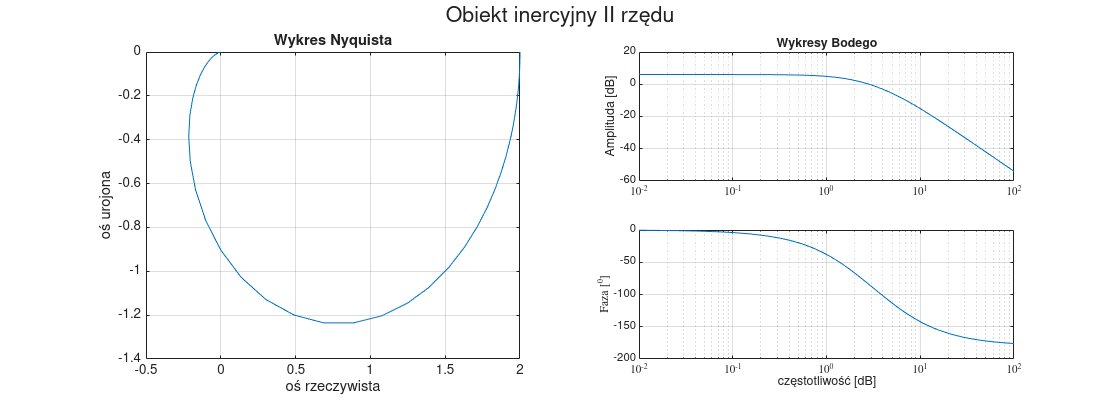

t=0:0.05:5;
dl=length(t);

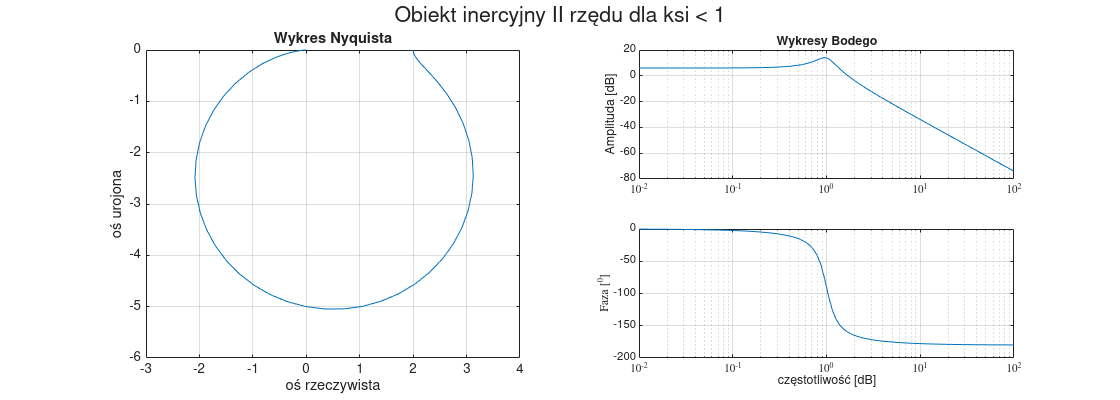

LiczbaWykresow=12;
y=zeros(dl,LiczbaWykresow);

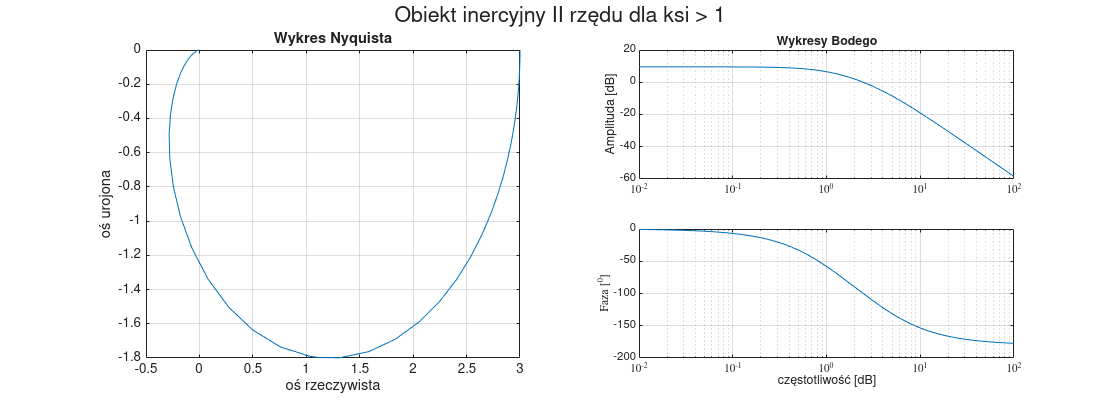

    title('Odpowiedź skokowa')
n=1;

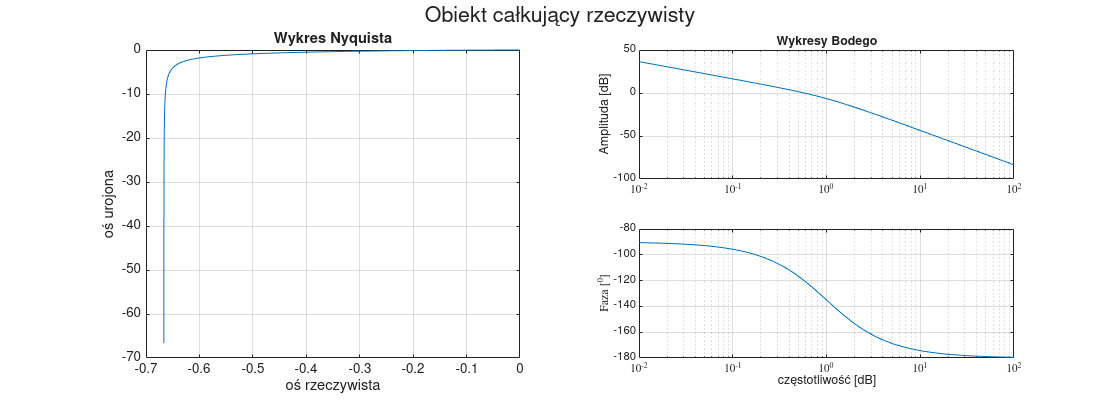

while(n<=LiczbaWykresow)
    [licz,mian]=zp2tf([],[-n/4+3*i -n/4-3*i], (n/4)^2+9);

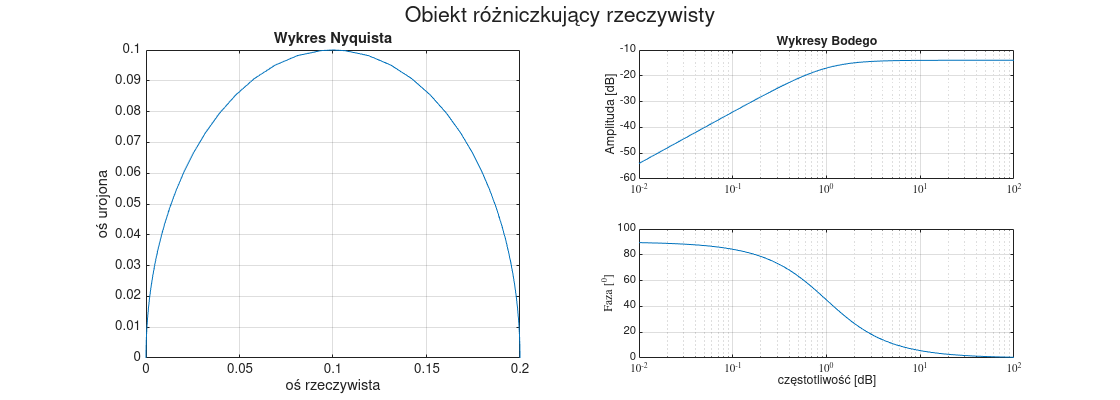

    [y(1:dl,n),x,tt]=step(licz,mian,t);
    n=n+1;

end
mesh(t,1:12,y');

# Charakterystyki częstotliwościowe podstawowych obiektów dynamicznych

W kolejnym etapie przeprowadzono badanie charakterystyk częstotliwośćiowych. W tym celu skorzystano z wykresów Nyquista oraz Bodego. Charakterystyki wykreślono dla wcześniej skonstruowanych obiektów automatyki określonych we wcześniejszym punkcie.

Do analizy charakterystyk częstotliwościowych skorzystano  z wcześniej zdefiniowanych obiektów. Dodatkowo w celu zautomatyzowania wyświetlania wykresów napisano następującą funkcję:

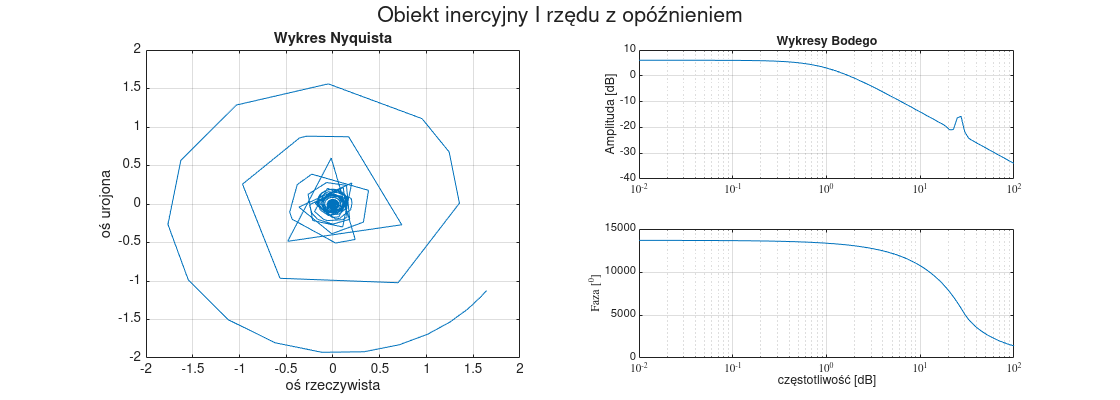

function frequency_respone(sys, plotTitle)

    %FREQUENCY_RESPONE plotting nyquist and 
    
    omega = logspace(-2, 2,100);
    
    clf;
    set(gcf, 'Position', [100, 100, 1400, 500]);
    
    sgtitle(plotTitle, 'Fontsize',16);
    
    subplot(2,2,[1 3])
    [Re, Im] = nyquist(sys);
    plot(Re(:), Im(:))
    title("Wykres Nyquista")
    ylabel('oś urojona')
    xlabel('oś rzeczywista')
    grid on

    [A, F] = bode(sys, omega);
    A_db = 20*log10(A(:));

    subplot(2,2, 2)
    semilogx(omega,A_db);
    title('Wykresy Bodego')
    ylabel("Amplituda [dB]")
    grid on

    subplot(2,2,4)
    semilogx(omega, F(:))
    ylabel("Faza [$^{0}$]", "Interpreter","latex")
    xlabel("częstotliwość [dB]")
    
    grid on
end

title_obiekt ='Obiekt inercyjny I rzędu';
frequency_respone(obiekt_inercyjny_rzedu_I_v1, title_obiekt)
title_obiekt ='Obiekt inercyjny II rzędu';
frequency_respone(obiekt_inercyjny_rzedu_II_v1, title_obiekt)
title_obiekt ='Obiekt inercyjny II rzędu dla ksi < 1';
frequency_respone(obiekt_inercyjny_rzedu_II_ver2_v1, title_obiekt)
title_obiekt ='Obiekt inercyjny II rzędu dla ksi > 1';
frequency_respone(obiekt_inercyjny_rzedu_II_ver2_v2, title_obiekt)
title_obiekt ='Obiekt całkujący rzeczywisty';
frequency_respone(obiekt_calk_recz_v1, title_obiekt)
title_obiekt ='Obiekt różniczkujący rzeczywisty';
frequency_respone(obiekt_rozn_recz_v1, title_obiekt)

Można wywnioskować na podstawie poniższego wykresu można zauważyć, że w pewnych punktach funkcja traci swoją gładkość. Prawdopodobnie jest to związane z aproksymacją, którą opisano w podpunkcie dla charakterysyki czasowej obiektu inercyjnego I rzędu z opóżnieniem.

title_obiekt ='Obiekt inercyjny I rzędu z opóźnieniem';
frequency_respone(obiekt_op_inercyjny_rzedu_I_v1, title_obiekt)

# Wnioski

Na ćwiczeniach zapoznano się z metodami tworzenia i przedstawiania charakterystyk czasowych i częstotliwościowych obiektów automatyki. Poznanie podstawowych rodzajów obiiektów oraz ich wykresów jest bardzo istotne w praktyce, aby umożliwić szybkie rozpoznawanie z czym aktualniie pracujemy, przez dopasowanie wykresów do aktualnie badanego zjawiska. Wydaję mi się, że jest to jedno z podstawowych narzędzi i ta część wiedzy, która będzie mi towarzyszyć przez większość czasu, gdy będę zajmował się automatyką.